# Exercise 2

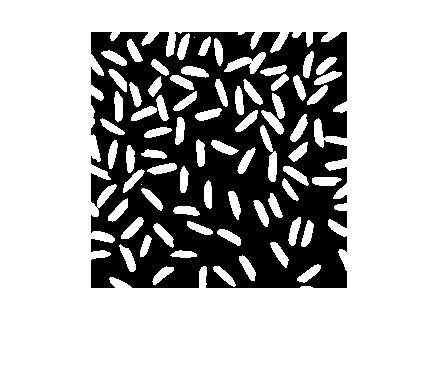

im=imread('rice.gif');
im = imbinarize(im); %binarize image
imshow(im);

[L,n]=bwlabel(im);
imshow(L);

D=regionprops(L,'Area'); % geeft alle area sizes in pixels
D2=regionprops(L,'PixelList') % geeft alle pixels per area

D2 = 99×1 struct array with fields:
    PixelList



D= struct2array(D) % area opzetten in array

D =    138   121    68   178   157   286   196   134   176   208   199   189   216   143    61   221   224   233   197   197   189   177   206   151   130   168     1   199   189   217   154   151   187   222   191   186   192   153   197   196   210   197     5   184   219   184     1   209   203   140


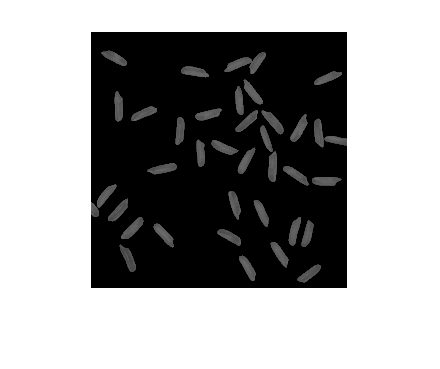

T=200

for i=1:length(D) % ga heel D af
    if D(i)<T
        pixels = struct2array(D2(i,1)); % pixels is matrix van alle pixels uit de area D(i), met eerst kolom y-cor en 2de x-cor
        for j=1:size(pixels,1) % ga alle pixels af
            im(pixels(j,2),pixels(j,1))=0; % de in de image de coordinaten van die pixels op zwart
        end
    end
end

im2=imread('rice.gif').*uint8(im); % door terug met originele te vermenigvuldigen krijgen we de grijze tineten terug
imshow(im2)

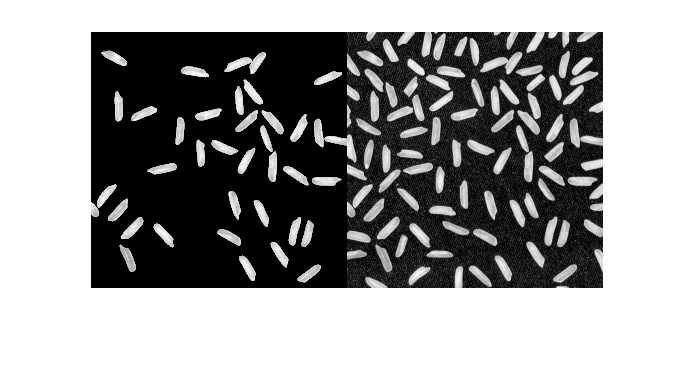

[L,n2]=bwlabel(im);
imshowpair(im2,(imread('rice.gif')),'montage')